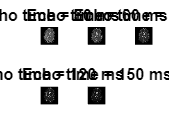

load('proj1aData_QFI'); % T2
[nRows, nCols, nTE] = size(image_3d);

figure
subplot(2, 3, 1)
imagesc(squeeze(image_3d(:, :, 1)))
intLimits_v = get(gca, 'CLim');
axis image
axis off
colormap(gray)
title(['Echo time = ', num2str(te_v(1)*1000), ' ms'])

for index = 2:nTE
	subplot(2, 3, index)
	imagesc(squeeze(image_3d(:, :, index)), intLimits_v)
	axis image
	axis off
	title(['Echo time = ', num2str(te_v(index)*1000), ' ms'])
end

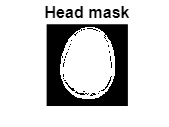

% Use the magnitude of the first image to form a binary mask  
image_m = squeeze(image_3d(:, :, 1));
mask_m = (image_m > 0.05*max(image_m(:))); % set mask at higher threshold 
figure
imagesc(mask_m)
colormap(gray)
axis image
axis off
title('Head mask')

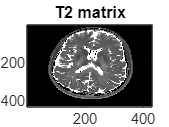

% Fitting a line to the ln(S) vs. TE data
t2_m = zeros(nRows,nCols);
s0_m = zeros(nRows,nCols);

for row = 1:nRows
    for col = 1: nCols
        if (mask_m(row, col) == 1)
            signal_v = squeeze(image_3d(row, col, :)); % that pixel in all images
            % Insert your code here to fit the natural log of the signal to a first order 
            % polynomial in TE:
	        coeff_v = polyfit(te_v, log(signal_v), 1);
	        slope = coeff_v(1);
	        logS0 = coeff_v(2);	% Intercept.
	        t2 = -1 / slope;
            t2_m(row, col) = t2;
            s0_m(row,col) = exp(logS0); 
        end
    end
end 
imagesc(t2_m, [0, 0.2])
title('T2 matrix')

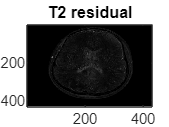

t2_residual = zeros(nRows,nCols);
for row = 1:nRows
    for col = 1: nCols
        if (mask_m(row, col) == 1)
            signal_v = squeeze(image_3d(row, col, :)); % that pixel in all images
            signal_model = exp( -te_v/t2_m(row,col) + log(s0_m(row,col)) );
            signal_diffence = abs(signal_model - signal_v);
            t2_residual(row, col) = norm(signal_diffence);
        end
    end
end
imagesc(t2_residual)
title('T2 residual')

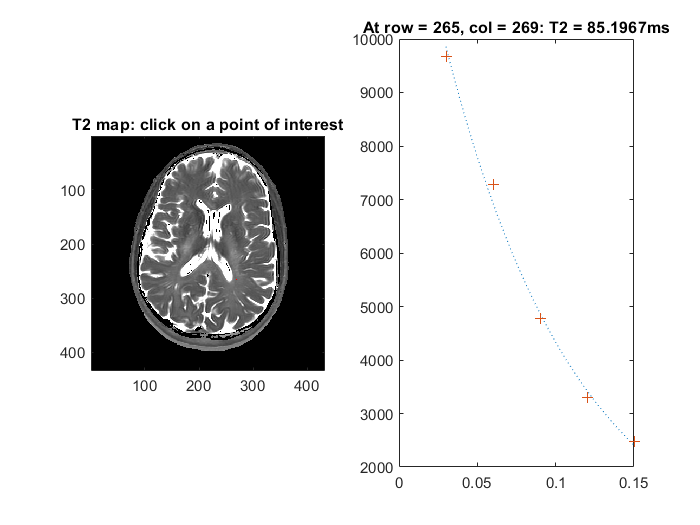

% View fit:
figure
subplot(1, 2, 1)
t2Max = 0.2;        % 0.2 s maximum value for display.
t2ceil_m = min(t2_m, t2Max*ones(nRows, nCols));
red0_m = t2ceil_m/t2Max;
green0_m = t2ceil_m/t2Max;
blue0_m = t2ceil_m/t2Max;
color_3d = cat(3, red0_m, green0_m, blue0_m);
image(color_3d)
axis image
title('T2 map: click on a point of interest')

nPoints = 50;
contFlag = 1;
while (contFlag == 1)
    % Get position of mouse-click on image:
    [x, y] = ginput(1);
    row = round(y);
    col = round(x);
    % Exit loop if the mouse click is outside the image:
    if (row < 1 | row > nRows | col < 1 | col > nCols)
        contFlag = 0;
        continue
    end
    red_m = red0_m;
    green_m = green0_m;
    blue_m = blue0_m;
    % Show the position of the pixel in red:
    red_m(row, col) = 1;
    green_m(row, col) = 0;
    blue_m(row, col) = 0;
    color_3d = cat(3, red_m, green_m, blue_m);
    image(color_3d)
    axis image
    title('T2 map: click on a point of interest')
    
    % Show fit:
    t2 = t2_m(row, col);
    s0 = s0_m(row, col);
    s_v = squeeze(image_3d(row, col, :));
    % creates nPoints between min(te) & max(te);
    teFit_v = linspace(min(te_v),max(te_v), nPoints);
    % Insert your code here to find the corresponding signal at each TE,
    % using your estimates of T2 and S0:
    sFit_v = exp( -teFit_v/t2 + log(s0) );
    subplot(1, 2, 2)
    plot(teFit_v, sFit_v, ':', te_v, s_v, '+')
    title(['At row = ', num2str(row), ', col = ', num2str(col), ': T2 = ', ...
        num2str(t2*1000), 'ms'])

    
end

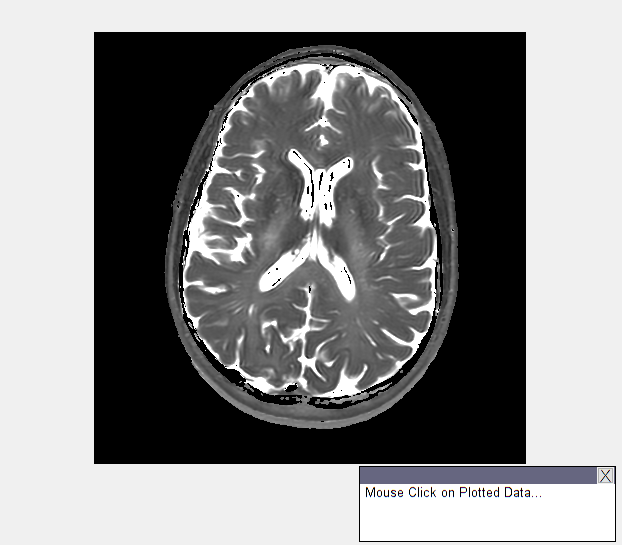

t2_grayscale = mat2gray(t2_m,[0,0.2]);
figure
imshow(t2_grayscale)
dcm = datacursormode;
dcm.Enable = 'on';
dcm.DisplayStyle = 'window';

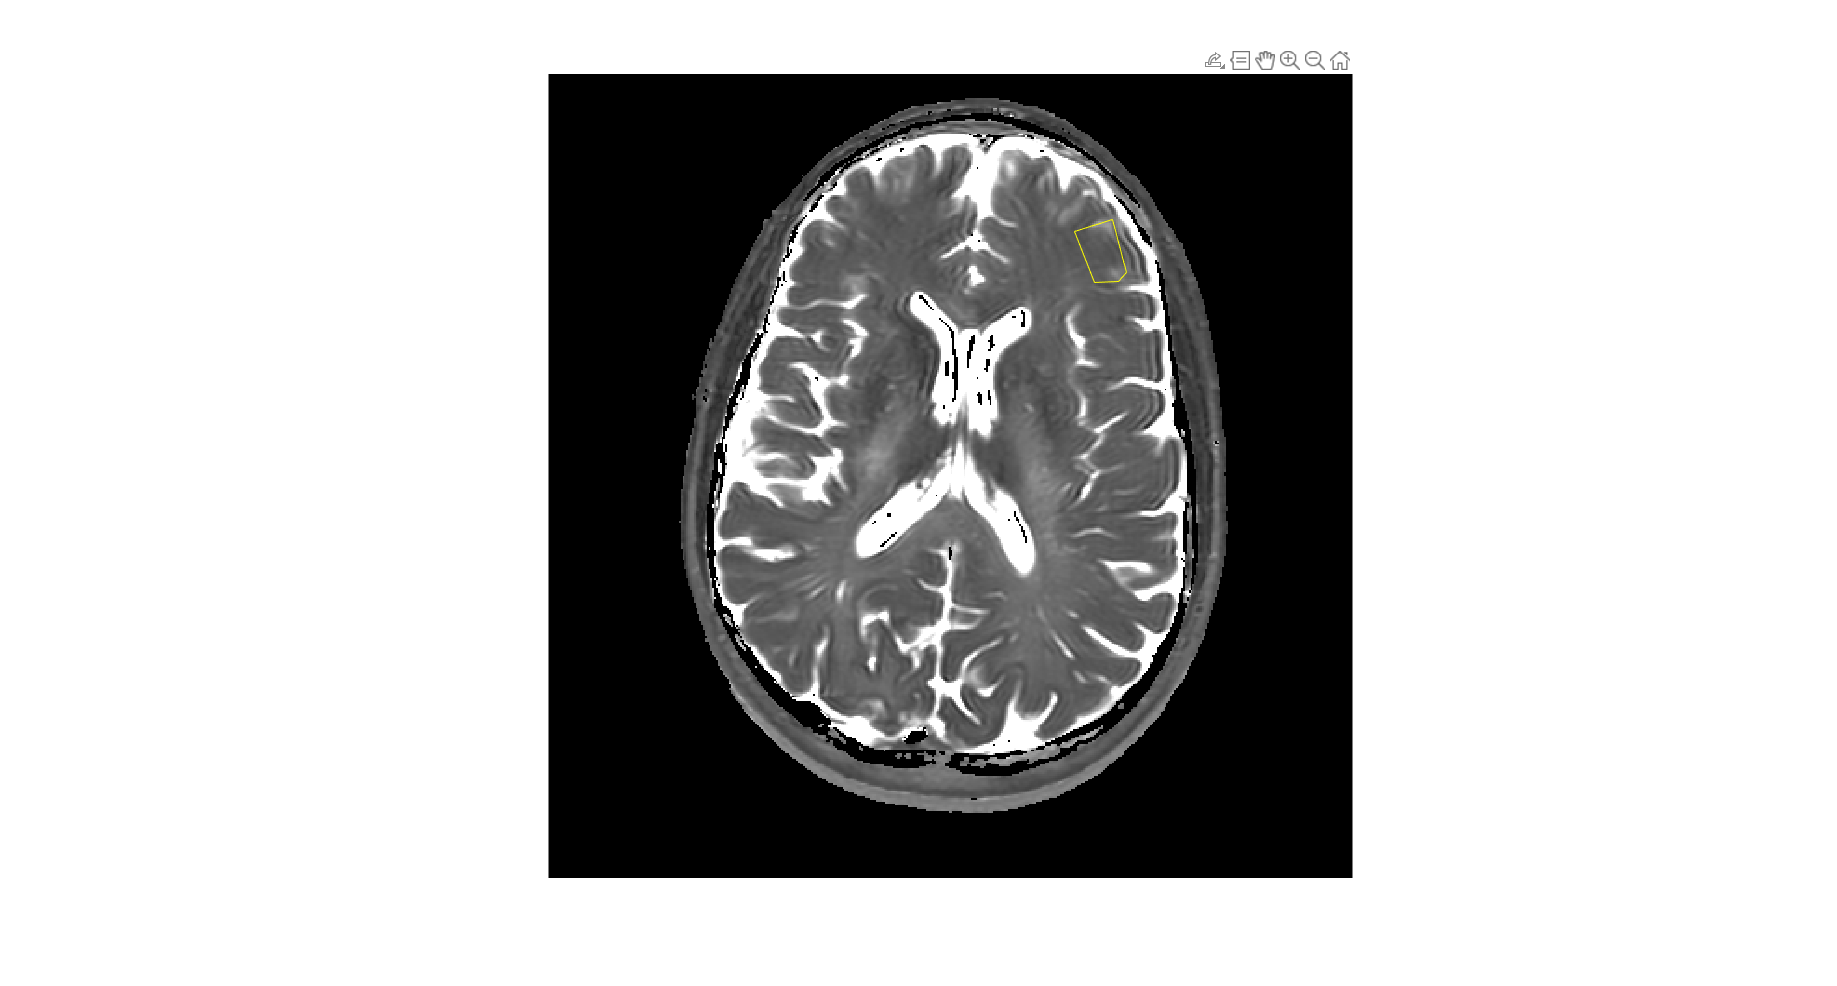

% Use T2 map to draw 
figure
imagesc(t2_m, [0,0.2])
axis image
axis off
colormap(gray)

[mask_gray, x_v, y_v] = roipoly ;
line(x_v, y_v, 'Color', 'y') ;

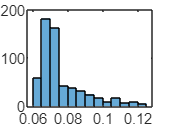

histogram(t2_m(mask_gray))

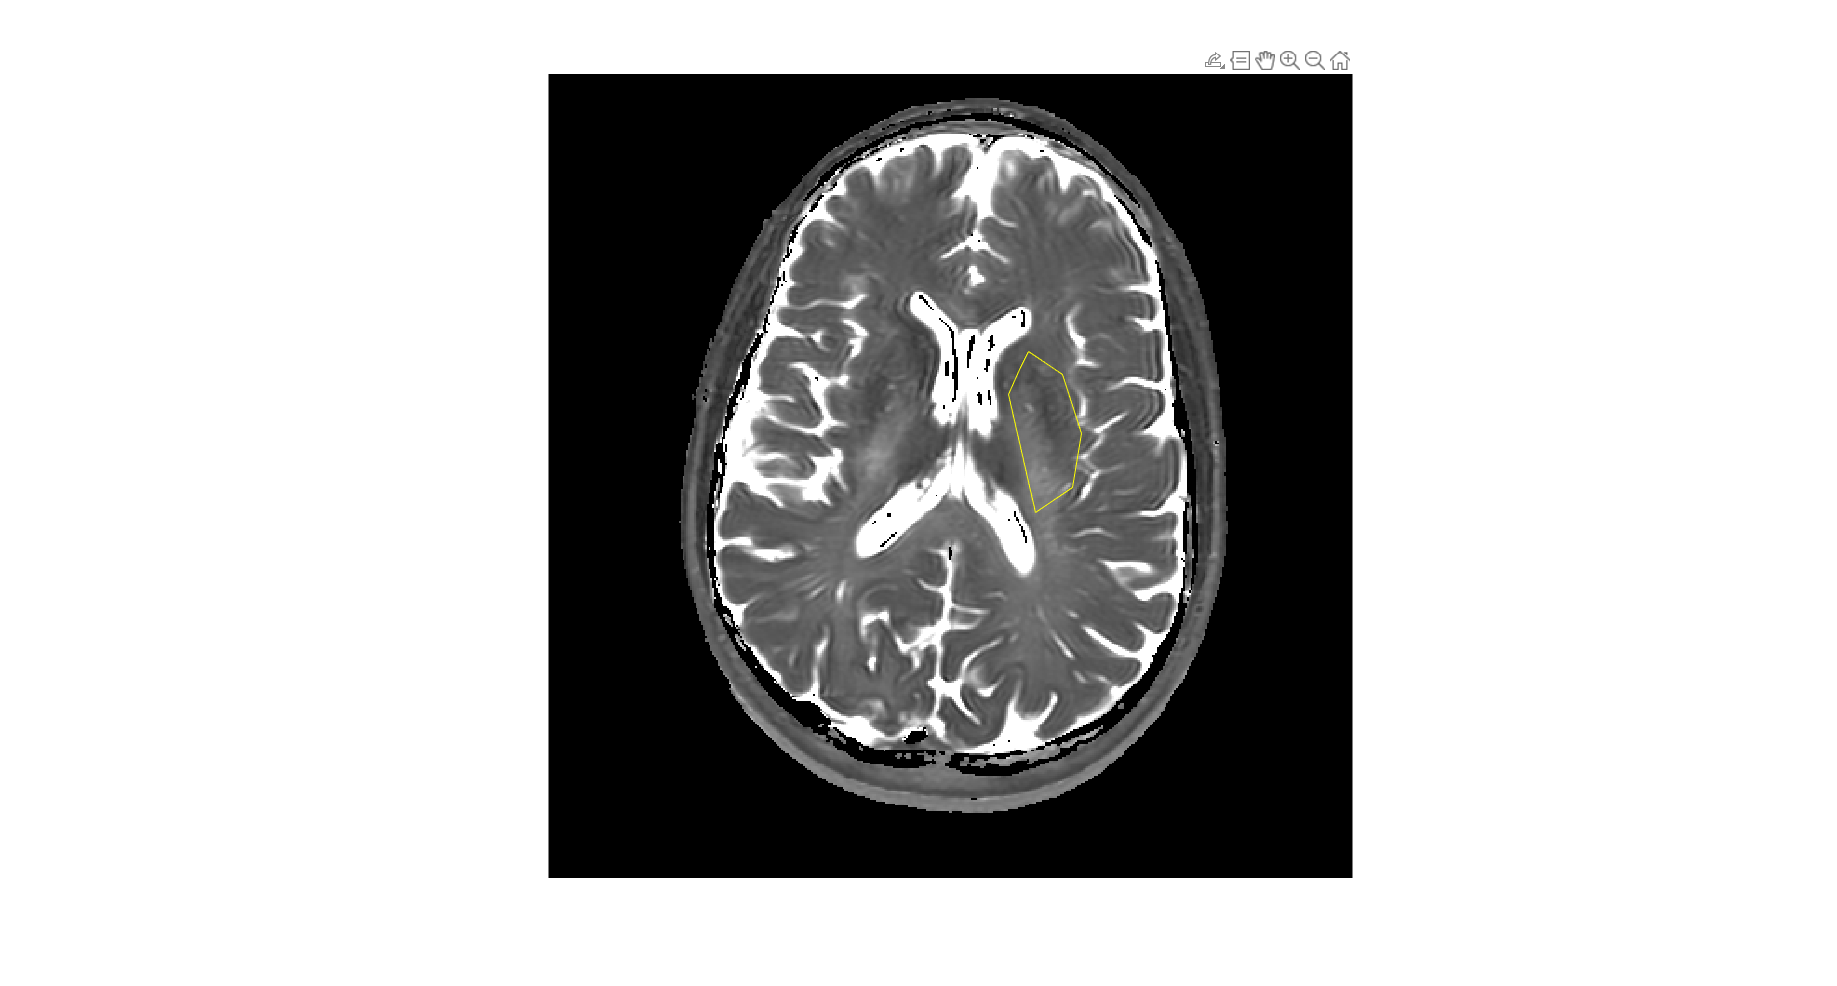

% Use T2 map to draw 
figure
imagesc(t2_m, [0,0.2]) %, intLimits_v)
axis image
axis off
colormap(gray)

[mask_white, x_v, y_v] = roipoly ;
line(x_v, y_v, 'Color', 'y') ;

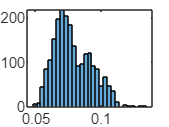

histogram(t2_m(mask_white))

t2_gray = t2_m(mask_gray) ;
mean_gray = mean(t2_gray(:))

mean_gray = 0.0764

std_grey = std(t2_gray(:))

std_grey = 0.0132


t2_white = t2_m(mask_white);
mean_white = mean(t2_white(:))

mean_white = 0.0788

std_white = std(t2_white(:))

std_white = 0.0141

std_gray_white = sqrt(std_white^2 + std_grey^2)

std_gray_white = 0.0193

% get rid of noisy data for T1

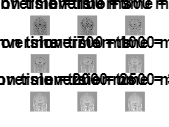

load('proj1bData_QFI')
[nRows, nCols, nTI] = size(irImage_3d);

figure
subplot(3, 3, 1)
intLimits_v = [min(irImage_3d(:)), max(irImage_3d(:))]; % get scaling to use for all images
imagesc(squeeze(irImage_3d(:, :, 1)), intLimits_v)
axis image
axis off
colormap(gray)
title(['Inversion time = ', num2str(ti_v(1)*1000), ' ms'])

for index = 2:nTI
	subplot(3, 3, index)
	imagesc(squeeze(irImage_3d(:, :, index)), intLimits_v)
	axis image
	axis off
	title(['Inversion time = ', num2str(ti_v(index)*1000), ' ms'])
end

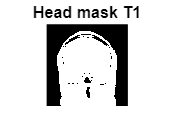

% Use the magnitude of the first image to form a binary mask  
image_m1 = squeeze(irImage_3d(:, :, end));
mask_m1 = (image_m1 > 0.1*max(image_m1(:))); % set mask at higher threshold 
figure
imagesc(mask_m1)
colormap(gray)
axis image
axis off
title('Head mask T1')

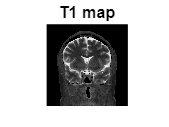

% Fitting a line to the Mz(S) vs. TI data
t1_m = zeros(nRows,nCols);
t1_residual = zeros(nRows,nCols);

for row = 1:nRows
    for col = 1: nCols
        if (mask_m1(row, col) == 1)
            M_z = squeeze(irImage_3d(row, col, :)); % that pixel in all images
            M_0 = m0_m(row, col);
            filtered_index = find(M_z<M_0);
            % Fit Mz vs TI
            coeff_v = polyfit(ti_v(filtered_index), -log(0.5.*(1-(M_z(filtered_index)./M_0))), 1);
	        slope = coeff_v(1);
	        t1 = 1 / slope;
            t1_m(row, col) = t1; 
            
            % Get norm
            t1_residual(row, col) = norm(M_z - M_0.*(1-2.*exp(-ti_v/t1)));
        end
    end
end 

figure
imagesc(t1_m)
axis off
axis image
colormap(gray)
title('T1 map')

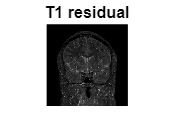

imagesc(t1_residual)
title('T1 residual')
axis image
axis off
colormap(gray)

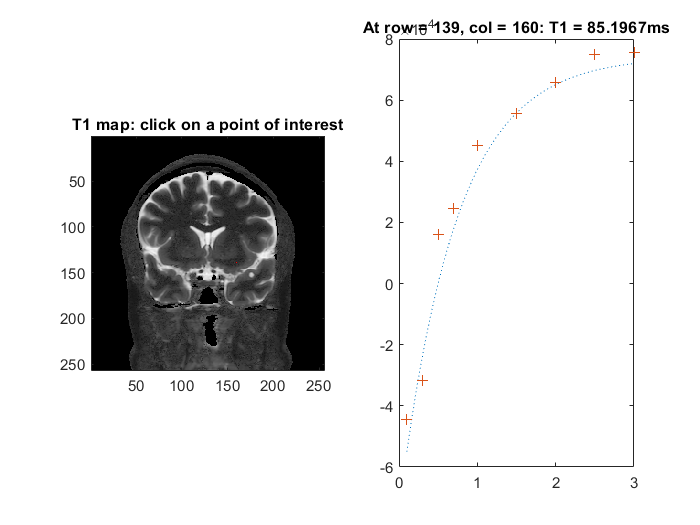

figure
subplot(1, 2, 1)
t1Max = max(max(t1_m));                        
t1ceil_m = min(t1_m, t1Max*ones(nRows, nCols));
red0_m = t1ceil_m/t1Max;
green0_m = t1ceil_m/t1Max;
blue0_m = t1ceil_m/t1Max;
color_3d = cat(3, red0_m, green0_m, blue0_m);
image(color_3d)
axis image
title('T1 map: click on a point of interest')

% Plot line
nPoints = 50;
contFlag = 1;
while (contFlag == 1)
    % Get position of mouse-click on image:
    [x, y] = ginput(1);
    row = round(y);
    col = round(x);
    % Exit loop if the mouse click is outside the image:
    if (row < 1 | row > nRows | col < 1 | col > nCols)
        contFlag = 0;
        continue
    end
    red_m = red0_m;
    green_m = green0_m;
    blue_m = blue0_m;
    % Show the position of the pixel in red:
    red_m(row, col) = 1;
    green_m(row, col) = 0;
    blue_m(row, col) = 0;
    color_3d = cat(3, red_m, green_m, blue_m);
    image(color_3d)
    axis image
    title('T1 map: click on a point of interest')
    
    % Show fit:
    Mz = squeeze(irImage_3d(row, col, :));
    M_0 = m0_m(row, col);
    t1 = t1_m(row, col);
    % creates nPoints between min(te) & max(te);
    tiFit_v = linspace(min(ti_v),max(ti_v), nPoints);
    MzFit = M_0.*(1-2.*exp(-tiFit_v/t1));
    
    subplot(1, 2, 2)
    plot(tiFit_v, MzFit, ':', ti_v, Mz, '+')
    title(['At row = ', num2str(row), ', col = ', num2str(col), ': T1 = ', ...
        num2str(t2*1000), 'ms'])
end

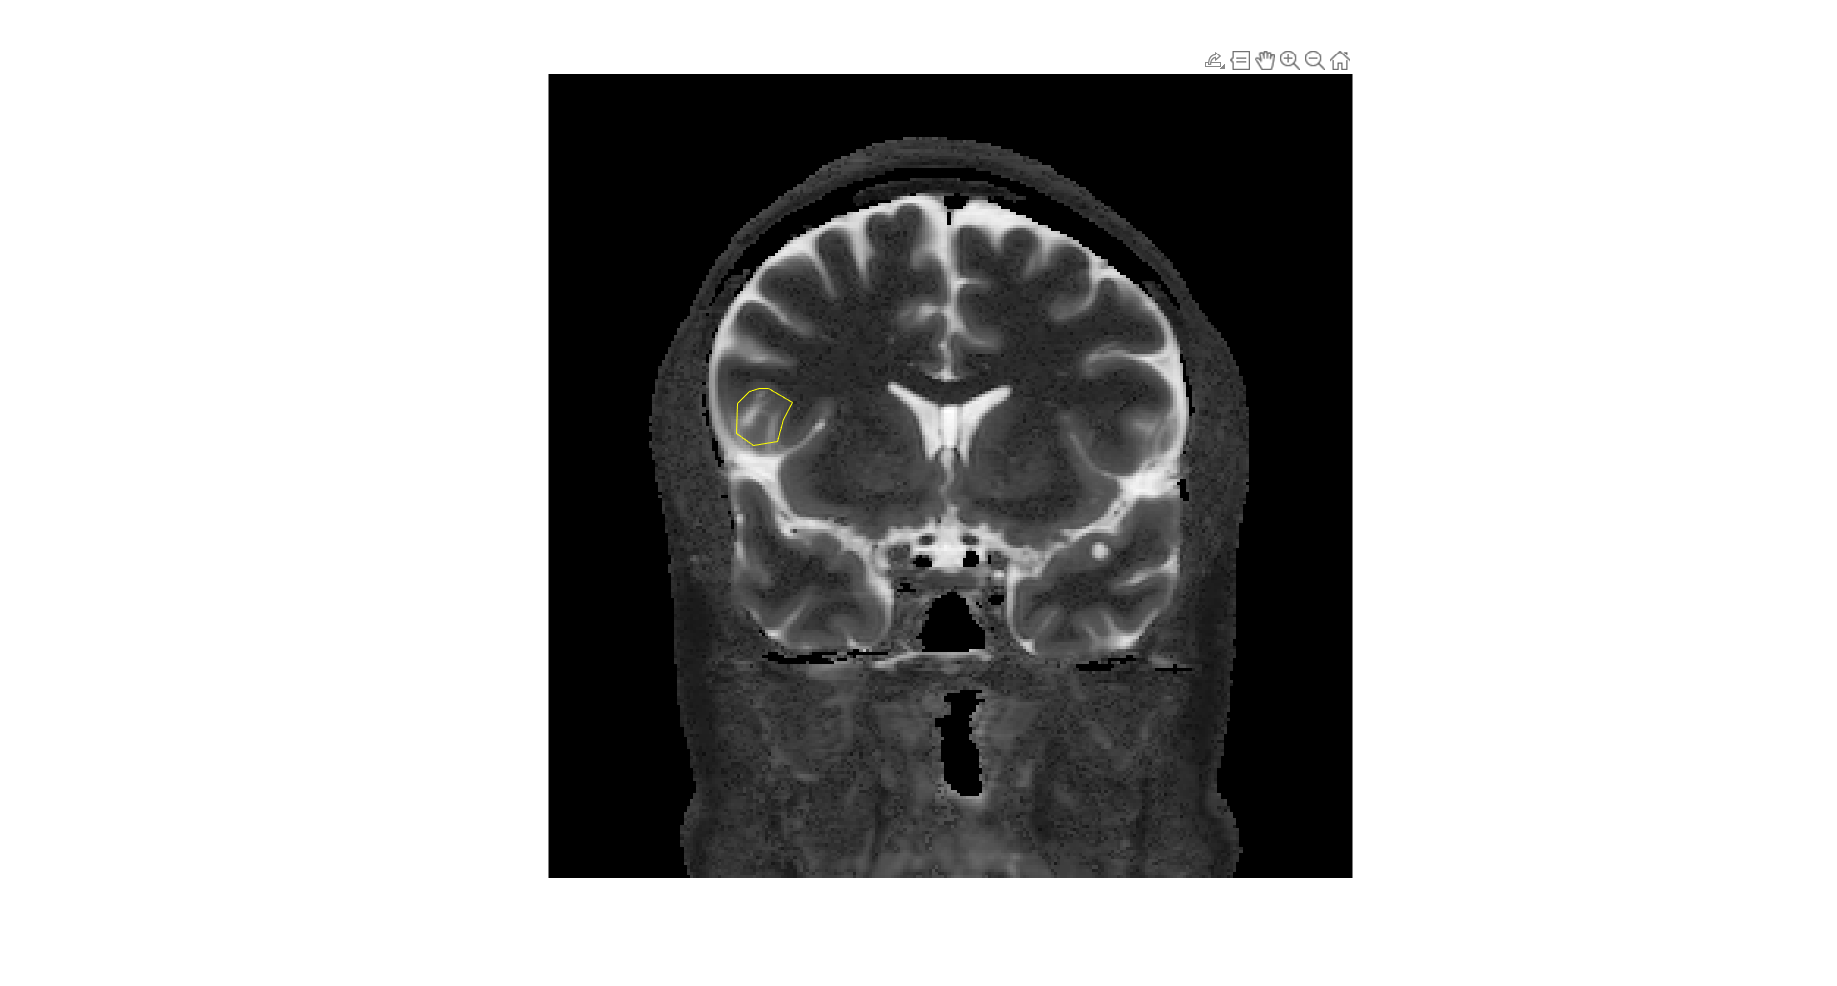

% Use T1 map to draw 
figure
intLimits_v = [min(irImage_3d(:)), max(irImage_3d(:))];
imagesc(t1_m) %, intLimits_v)
axis image
axis off
colormap(gray)
%title(['Inversion time = ', num2str(ti_v(1)*1000),'ms'])

[mask_gray, x_v, y_v] = roipoly ;
line(x_v, y_v, 'Color', 'y') ;

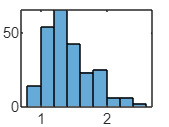

histogram(t1_m(mask_gray))

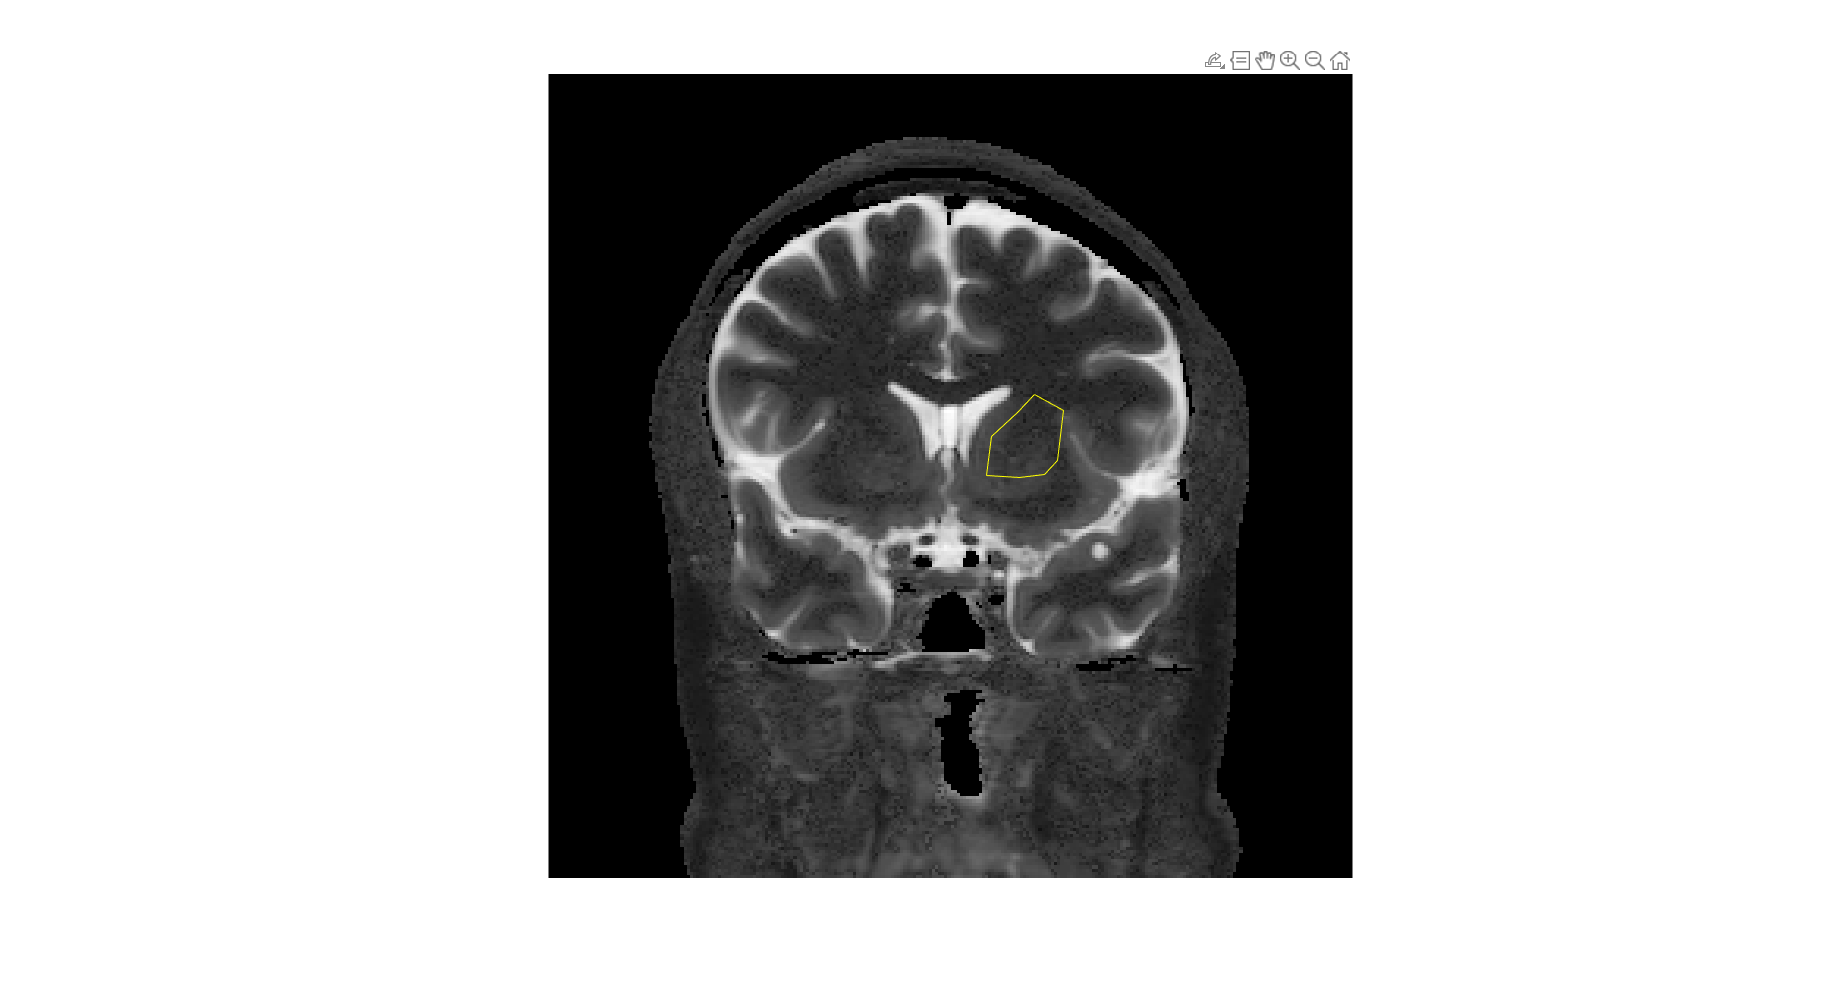

% Use T1 map to draw 
figure
intLimits_v = [min(irImage_3d(:)), max(irImage_3d(:))];
imagesc(t1_m) %, intLimits_v)
axis image
axis off
colormap(gray)
%title(['Inversion time = ', num2str(ti_v(1)*1000),'ms'])

[mask_white, x_v, y_v] = roipoly ;
line(x_v, y_v, 'Color', 'y') ;

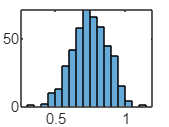

histogram(t1_m(mask_white))

t1_gray = t1_m(mask_gray) ;
mean_gray = mean(t1_gray(:))

mean_gray = 1.4236

std_grey = std(t1_gray(:))

std_grey = 0.3341


t1_white = t1_m(mask_white);
mean_white = mean(t1_white(:))

mean_white = 0.7503

std_white = std(t1_white(:))

std_white = 0.1263

std_gray_white = sqrt(std_white^2 + std_grey^2)

std_gray_white = 0.3571